open("fullcontroller.slx")

open("controller_no_heading.slx")

%26 Mille
%Finding values
clc
clear

dd = load('device-monitor-241120-090939.log');
time_start = 0;
time_end = 50;
time_slice = dd(dd(:,1) >= time_start & dd(:,1) <= time_end, :);
i_0 = mean(time_slice(:, 5));
time_start = 150;
time_end = 450;
time_slice = dd(dd(:,1) >= time_start & dd(:,1) <= time_end, :);
i_const = mean(time_slice(:, 5));

figure(1000)
hold on

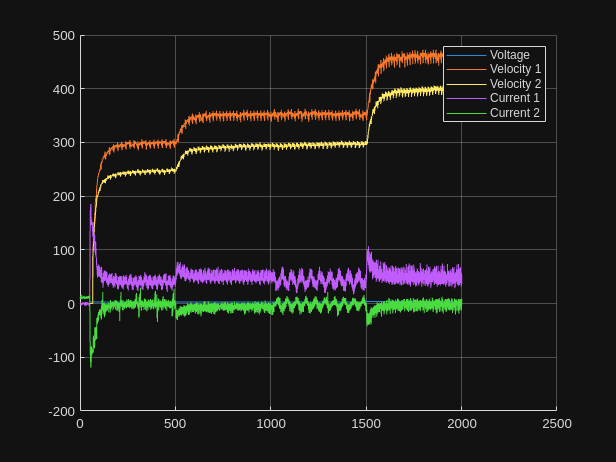

plot(dd(:,1), dd(:,2))
hold on
plot(dd(:,1), dd(:,3))
hold on
plot(dd(:,1), dd(:,4))
hold on
dd(:,5) = dd(:,5) - i_0;
plot(dd(:,1), dd(:,5))
hold on
dd(:,6) = dd(:,6) - i_0;
plot(dd(:,1), dd(:,6))
hold on
grid on
legend('Voltage', 'Velocity 1', 'Velocity 2', 'Current 1', 'Current 2')
hold off

M = 0.95;
wb = 0.15;
r = 0.065; % or 7 see which works best
wzi = r^2*M;
imax = max(dd(:,5))

imax = 185.5051

izero = mean(dd(1:100,6)) % 50ms

izero = 11.5051

i_ss = (imax - izero)*0.0045 % mA

i_ss = 0.7830

V_ss = 3;
R = V_ss / i_ss % Ohm

R = 3.8314

time_start_3v = 650;
time_end_3v = 1500;
ss_3v = dd(dd(:,1) >= time_start_3v & dd(:,1) <= time_end_3v, :);

time_start_4v = 1630;
time_end_4v = 2000;
ss_4v = dd(dd(:,1) >= time_start_4v & dd(:,1) <= time_end_4v, :);

omega_3v = mean(ss_3v(:, 3));
omega_4v = mean(ss_4v(:, 3));
tau = (omega_4v - omega_3v) * 0.63

tau = 68.2082

L = R*0.001 % H

L = 0.0038

i_ss = 0.071; % define i_ss for our robot
v_R = i_ss*L

v_R = 2.7203e-04

v_e = 3 - v_R % back EMF

v_e = 2.9997

K_b = v_e / omega_3v % rad/s

K_b = 0.0085

K_t = K_b;
D = (i_ss*K_b) / omega_3v

D = 1.7185e-06

J = ((D*R + K_t*K_b) / R) * (tau/1000)

J = 1.4097e-06

time_start = 1500;
time_end = 1585;
time_slice = dd(dd(:,1) >= time_start & dd(:,1) <= time_end, :);
mean(time_slice(:, 5));
current_time = 27.677 * 0.63

current_time = 17.4365

s = tf('s');
G = (K_t * 10^7) / ((J*L*s^2 + D*L*s + J*R*s + D*R + K_t*K_b) * 10^7)

G =
 
            8.521e04
  -----------------------------
  0.05401 s^2 + 54.08 s + 791.9
 
Continuous-time transfer function.
Model Properties


## Matlab motor model

Vmax = 9;     % max motor voltage
gear = 9.6;
Wrad = 0.03;  % wheel radius
detect_delay = 0.01; % velocity delay
Gn = [K_t];
Gd = [J*L, D*L+J*R, D*R + K_t*K_b];
G = minreal(tf(Gn, Gd));
Ts = 0.004;
G.OutputDelay = detect_delay;
Gz = c2d(G, Ts,'zoh')

Gz =
 
           1.783 z^2 + 4.183 z + 0.1257
  z^(-3) * ----------------------------
             z^2 - 0.9616 z + 0.01823
 
Sample time: 0.004 seconds
Discrete-time transfer function.
Model Properties


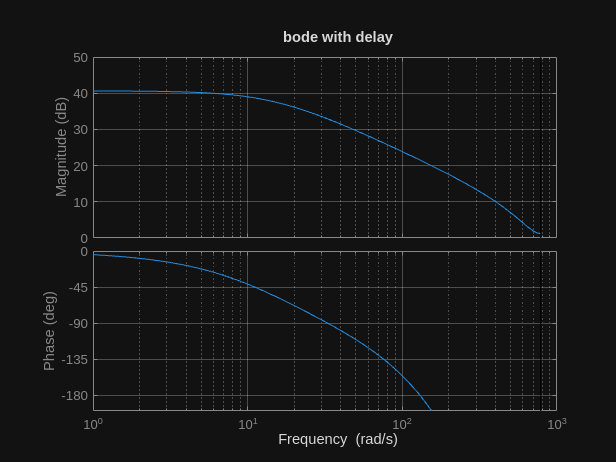

MathWorks::System::IUserException in WebControllerFactory::create(): [Unrecognized method, property, or field 'ViewModel' for class 'handle'.

Error in matlab.ui.internal.componentframework.WebComponentController/getParentView (line 476)
            parentView = parentController.ViewModel;

Error in 

bode(Gz)
grid on
title("bode with delay")
axis([1,1000,-200,0])

## controller

[mag,phase,wout] = bode(Gz);
Wc   = interp1( squeeze(phase), wout, -75) % crossover frequency

Wc = 23.4016

sys = Gz;
N = 2;
taui = N/Wc

taui = 0.0855

mag = bode(Gz,Wc) % get magnitude at wc

mag = 57.6465

Kp = 0.03 % calculate Kp

Kp = 0.0300

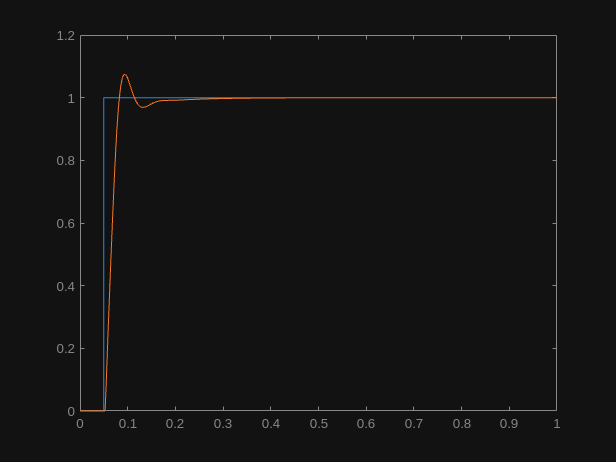

out = sim("pi_controller.slx",1);  %’basebot_model.slx’
plot(out.simout.Time, out.simout.Data(:,1),out.simout.Time, out.simout.Data(:,2));

## Turn controller

out = sim('controller_no_turnrate.slx', 1.5);

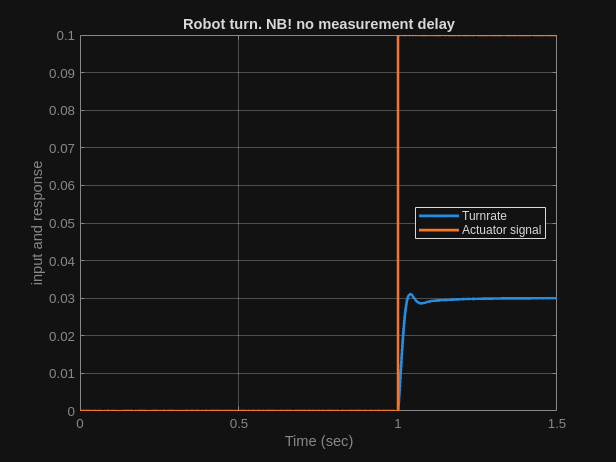

plot(out.turn_tf.Time(:), out.turn_tf.Data(:,1),out.turn_tf.Time(:), out.turn_tf.Data(:,2),'LineWidth',2)
legend('Turnrate','Actuator signal','Location','east')
grid on
xlabel('Time (sec)')
ylabel('input and response')
title('Robot turn. NB! no measurement delay')

out = sim('controller_no_turnrate.slx', 3);
% resample with constant sample time
Ts = 0.004;
timeVec = 0.5:Ts:2.5;
tsout = resample(out.turn_tf,timeVec);
% Get in and out in separate vectors
idin = tsout.Data(:,2);
idout = tsout.Data(:,1);
% collect in structure
idd1 = iddata(idout, idin, Ts);
% estimate
sys20 = tfest(idd1, 2, 0);
sys32 = tfest(idd1, 3, 2)

sys32 =
 
  From input "u1" to output "y1":
       7.757 s^2 + 2581 s + 3.16e04
  ---------------------------------------
  s^3 + 124.8 s^2 + 1.033e04 s + 1.053e05
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 3   Number of zeros: 2
   Number of free coefficients: 6
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "idd1".
Fit to estimation data: 99.93%                   
FPE: 8.83e-11, MSE: 8.518e-11                    
 
Model Properties


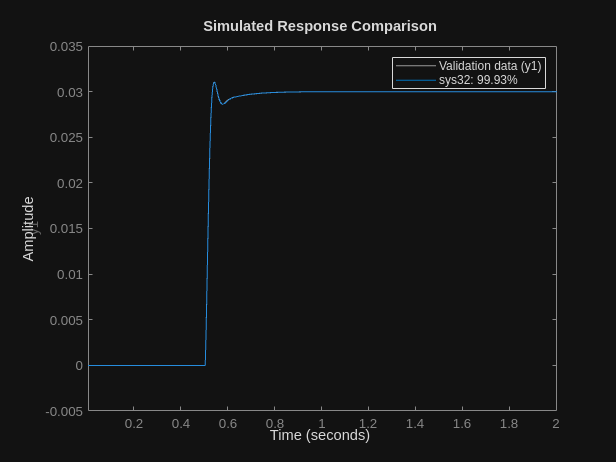

sys32_d = c2d(sys32,Ts,'zoh');
figure(20)
compare(sys32, idd1)

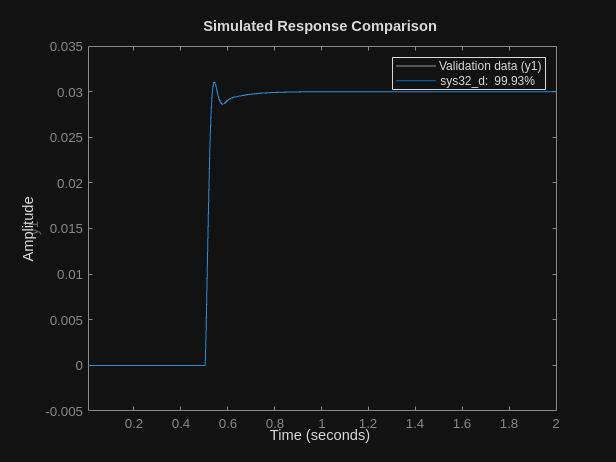

compare(sys32_d, idd1)

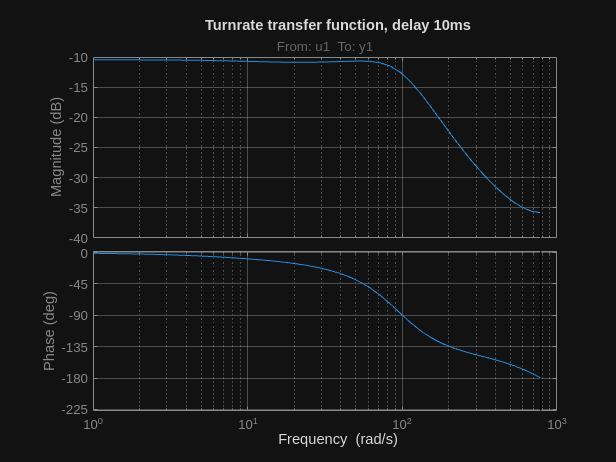

sys32.InputDelay=0.01;
bode(sys32_d)
title('Turnrate transfer function, delay 10ms')
grid on

[mag,phase,wout] = bode(sys32_d);
N = 2;
al = 0.1;
phi_i = -atan(1/N)*180/pi

phi_i = -26.5651

phi_d = asin((1-al)/(1+al))*180/pi

phi_d = 54.9032

Wc   = interp1( squeeze(phase), wout, (-120-phi_i-phi_d)) % crossover frequency

Wc = 322.7850

tautr = N/Wc

tautr = 0.0062

mag = bode(sys32_d,Wc) % get magnitude at wc

mag = 0.0353

kptr = 0.4; % calculate Kp
taud = 1/(sqrt(al)*Wc)

taud = 0.0098

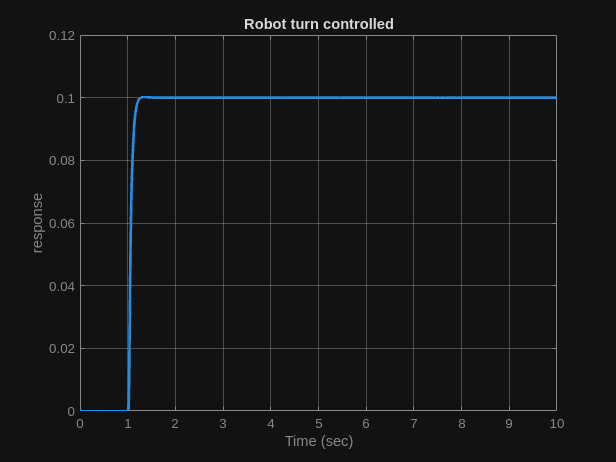

out = sim("controller_no_heading.slx",10);
plot(out.Turn_PI.Time(:), out.Turn_PI.Data(:,4),'LineWidth',2)
grid on
xlabel('Time (sec)')
ylabel('response')
title('Robot turn controlled')

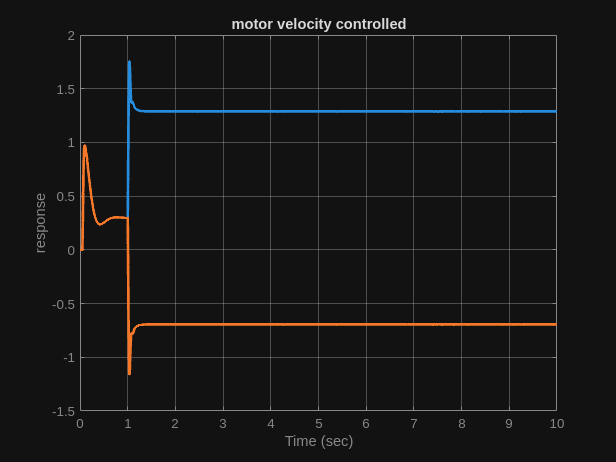

plot(out.turn_tf.Time(:),[out.turn_tf.Data(:,1),out.turn_tf.Data(:,2)],'LineWidth',2)
grid on
xlabel('Time (sec)')
ylabel('response')
title('motor velocity controlled')

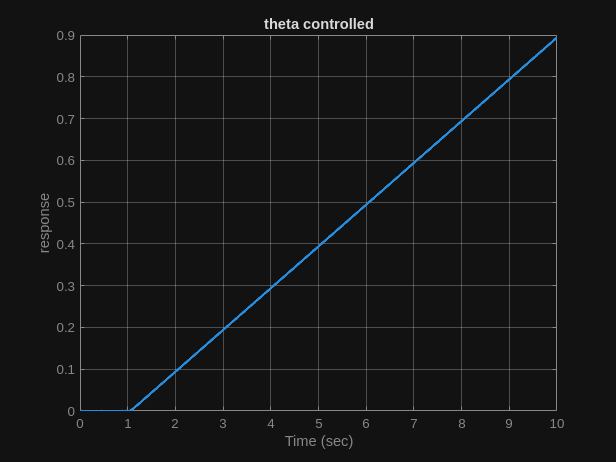

plot(out.pose.Time(:),out.pose.Data(:,2),'LineWidth',2)
grid on
xlabel('Time (sec)')
ylabel('response')
title('theta controlled')

## Heading controller

out = sim('controller_no_heading.slx', 3);

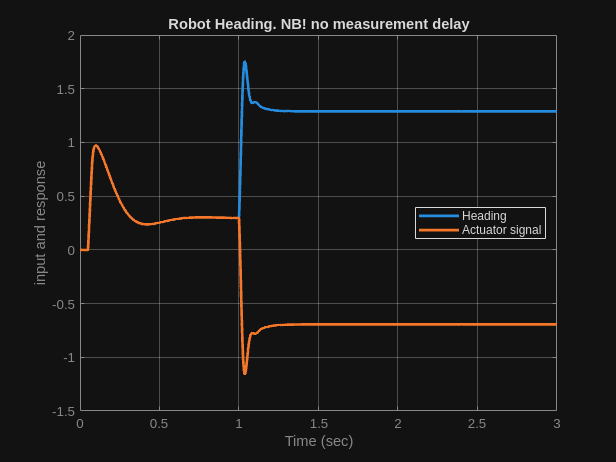

plot(out.turn_tf.Time(:), out.turn_tf.Data(:,1),out.turn_tf.Time(:), out.turn_tf.Data(:,2),'LineWidth',2)
legend('Heading','Actuator signal','Location','east')
grid on
xlabel('Time (sec)')
ylabel('input and response')
title('Robot Heading. NB! no measurement delay')

out = sim('controller_no_turnrate.slx', 3);
% resample with constant sample time
Ts = 0.004;
timeVec = 0.5:Ts:2.5;
tsout2 = resample(out.turn_tf,timeVec);
% Get in and out in separate vectors
idin2 = tsout2.Data(:,2);
idout2 = tsout2.Data(:,1);
% collect in structure
idd2 = iddata(idout2, idin2, Ts);
% estimate
sys62 = tfest(idd2, 3, 2)

sys62 =
 
  From input "u1" to output "y1":
       7.757 s^2 + 2581 s + 3.16e04
  ---------------------------------------
  s^3 + 124.8 s^2 + 1.033e04 s + 1.053e05
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 3   Number of zeros: 2
   Number of free coefficients: 6
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "idd2".
Fit to estimation data: 99.93%                   
FPE: 8.83e-11, MSE: 8.518e-11                    
 
Model Properties


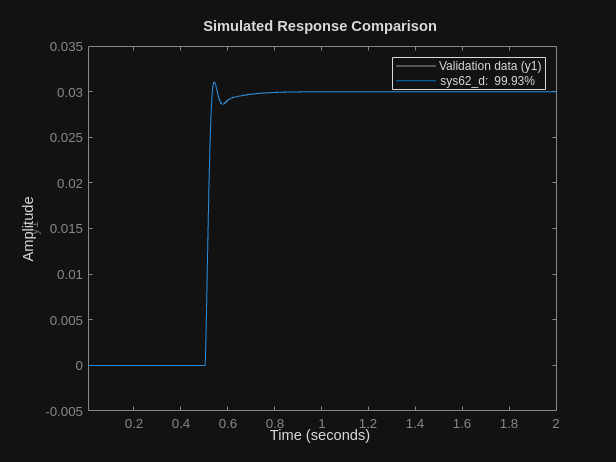

sys62_d = c2d(sys62,Ts,'zoh');
figure(20)
compare(sys62_d, idd2)

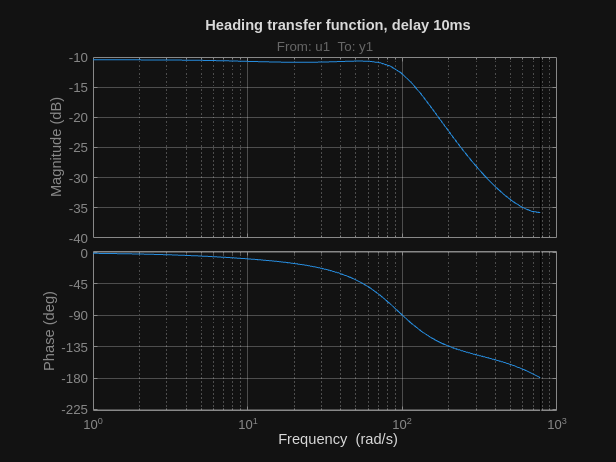

sys62.InputDelay=0.01;
bode(sys62_d)
title('Heading transfer function, delay 10ms')
grid on

[mag,phase,wout] = bode(sys62_d);
pole(sys62_d)

ans =    0.9543 + 0.0000i
   0.7608 + 0.2395i
   0.7608 - 0.2395i


N2 = 2;
al2 = 0.1;
phi_i2 = -atan(1/N2)*180/pi

phi_i2 = -26.5651

phi_d2 = asin((1-al2)/(1+al2))*180/pi

phi_d2 = 54.9032

Wc2   = interp1( squeeze(phase), wout, (-120-phi_i2-phi_d2)) % crossover frequency

Wc2 = 322.7850

tautr2 = N2/Wc2

tautr2 = 0.0062

mag2 = bode(sys62_d,Wc2) % get magnitude at wc

mag2 = 0.0353

kptr2 = 0.01; % calculate Kp
taud2 = 1/(sqrt(al2)*Wc2)

taud2 = 0.0098

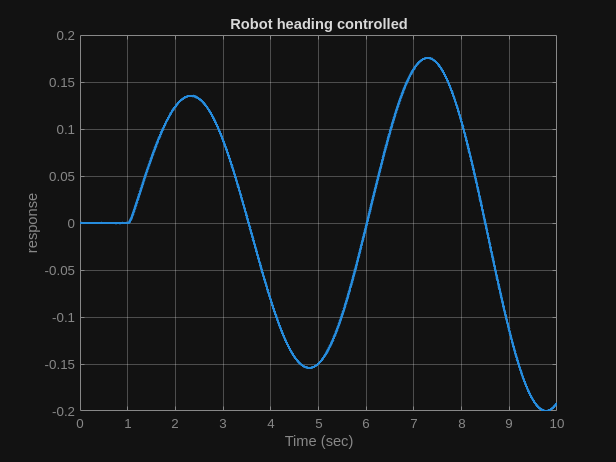

out = sim("fullcontroller.slx",10);
plot(out.pose.Time(:), out.pose.Data(:,6),'LineWidth',2)
grid on
xlabel('Time (sec)')
ylabel('response')
title('Robot heading controlled')